1. Revisiting normalization and Parseval. Since many are still having occasional spectral normalization issues, please choose any real time series we have used in this course and show that Parseval’s theorem is satisfied for i) 2 degrees of freedom (exactly) and ii) for ≈ 10−20 half-overlapped segments with a correctly normalized Hanning window (approximately: say a few percent). 

df = struct;
df.t = double(ncread("autoss_scripps_pier-2021.nc",'time'))/3600/24+datenum(1970,1,1);
df.T = ncread("autoss_scripps_pier-2021.nc",'temperature');
df.dt=mean(diff(df.t),'omitnan');
%make divisible by 20 chunks
i = 10001;
j=110000;
df.t = df.t(i:j);
df.T = df.T(i:j);

%2 degrees of freedom:
%calculate spectra
data = struct;
[data.spectra,data.f_vector,data.df] = Spectra2(df.T,df.dt,'none');
%check Parseval's theorem
[data.p,data.variance,data.sum_spec] = Parseval(df.T,data.spectra,data.df);
disp(['2 degrees of freedom: ', num2str(data.p)])

2 degrees of freedom: 0.99999


%19 overlapping chunks
df_Chunks = SegmentData(df,(length(df.T)/10));
%Hanning window
df_Chunks.dt=mean(diff(df_Chunks.t),"all",'omitnan');
[data.spectra,data.f_vector,data.df] = Spectra2(df_Chunks.T,df.dt,'Hanning');
%check Parseval's theorem
[data.p,data.variance,data.sum_spec] = Parseval(df.T,data.spectra,data.df);
%Hanning, 50% overlapping 1.9 DoF/Segment
disp(['~36 degrees of freedom: ', num2str(data.p)])

~36 degrees of freedom: 1.0472


2. Aliasing. The Surface Water and Ocean Topography (SWOT) satellite is due to launch soon. It has two planned orbits. The initial calibration and validation will be carried out with a fast-sampling orbit, with an exact repeat of about a day, and the subsequent science mission will have about a 21-day repeat. Specific time periods are listed in the table below: 

Orbit period      | (days) 

Fast-sampling  | 0.99349 

Science            | 20.86455 

How will the following tidal frequencies be aliased by the satellite orbit? How long should the satellite operate in each orbit in order to separate these frequencies? 

- Aliased frequnecies calculated below.

- The satellite will have to stay in orbit for the maximum time needed to measure the frequencies to tell them apart. This means 152.6098 days for the Fast-Sample orbit and 154.0388 days for the Scientific Orbit.

%Fast-Sampling
Alias2(24,0.99349)

The 1 CPD oscillation sampled at 0.99349-day intervals aliases to 152.6098 days


Alias2(12.9054,0.99349)

The 1.8597 CPD oscillation sampled at 0.99349-day intervals aliases to 6.5181 days


Alias2(12.6583,0.99349)

The 1.896 CPD oscillation sampled at 0.99349-day intervals aliases to 8.5385 days


Alias2(12.4206,0.99349)

The 1.9323 CPD oscillation sampled at 0.99349-day intervals aliases to 12.3714 days


Alias2(12.00,0.99349)

The 2 CPD oscillation sampled at 0.99349-day intervals aliases to 76.3049 days


Alias2(11.9672,0.99349)

The 2.0055 CPD oscillation sampled at 0.99349-day intervals aliases to 131.1705 days


%Scientific-Sampling
Alias2(24,20.86455)

The 1 CPD oscillation sampled at 20.8646-day intervals aliases to 154.0388 days


Alias2(12.9054,20.86455)

The 1.8597 CPD oscillation sampled at 20.8646-day intervals aliases to 105.1243 days


Alias2(12.6583,20.86455)

The 1.896 CPD oscillation sampled at 20.8646-day intervals aliases to 47.3078 days


Alias2(12.4206,20.86455)

The 1.9323 CPD oscillation sampled at 20.8646-day intervals aliases to 66.0222 days


Alias2(12.00,20.86455)

The 2 CPD oscillation sampled at 20.8646-day intervals aliases to 77.0194 days


Alias2(11.9672,20.86455)

The 2.0055 CPD oscillation sampled at 20.8646-day intervals aliases to 133.2961 days


3. Spectra of aliased signals. Use the same wind speed time series that you used for problem set #5, with the same gap filling and 60-day segments. 

addpath('/Users/benjaminwerb/Documents/GitHub/SIO221a_Github_code/HW5_data/');
%make struct
df = Structify('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc' ...
    ,'OS_T8S110W_DM183A-20160321_D_WIND_10min.nc', ...
    'OS_T8S110W_DM231A-20170606_D_WIND_10min.nc');
df = FillGaps(df); %Fill gaps with lin interp
Chunks = Chunkify(df); %60 day chunks

a. Subsample the data set every 40 data points (6.667 hours) and recompute the spectrum. 

Chunks.WSPD_S = Chunks.WSPD(1:40:end,:);
df.t_S = df.t(1:40:end); %subsample
dt=mean(diff(df.t_S),'omitnan');
[spectra,f_vector,dfrq,dfn] = Spectra2(Chunks.WSPD_S,dt,'none');

b. Compare the resulting spectrum with the spectrum that you obtained for the full data set by overlaying the subsampled plot over your earlier result. 

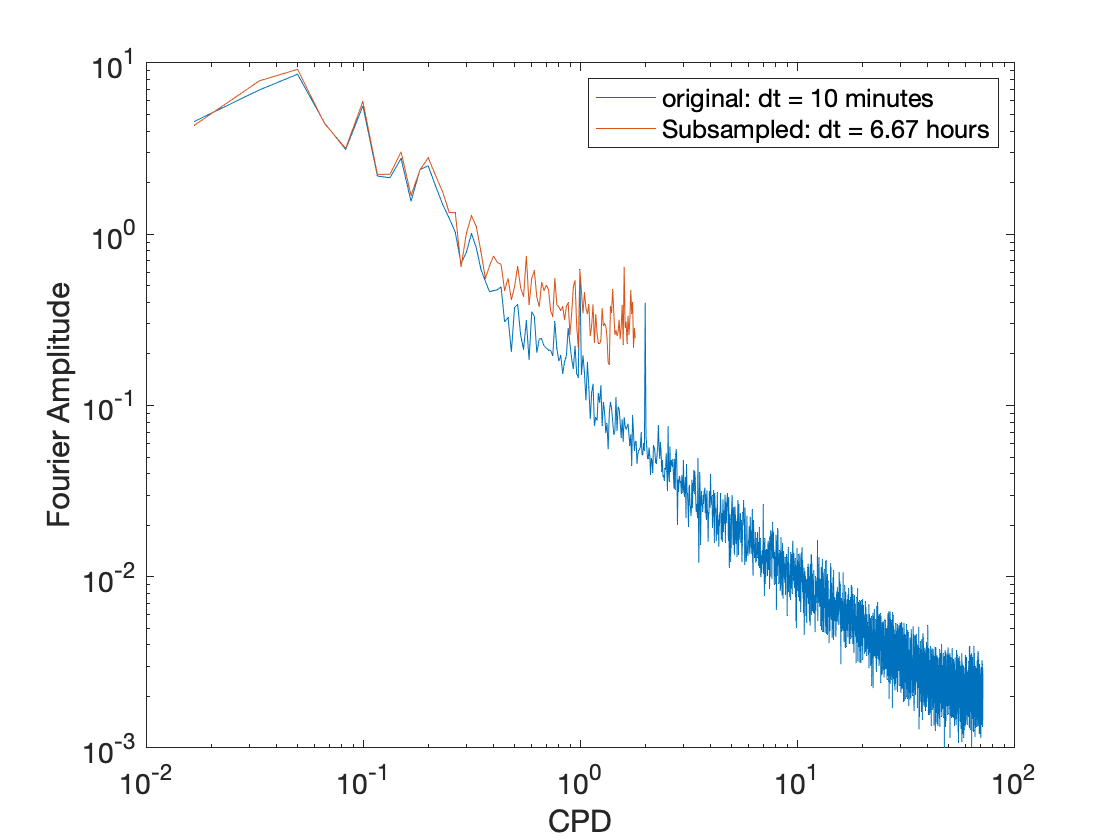

dt2=mean(diff(df.t),'omitnan');
[spectra2,f_vector2,dfrq2,dfn2] = Spectra2(Chunks.WSPD,dt2,'none');

figure(1)
clf
loglog(f_vector2,spectra2)
hold on
loglog(f_vector,spectra)
xlabel('CPD')
ylabel('Fourier Amplitude')
legend('original: dt = 10 minutes','Subsampled: dt = 6.67 hours')

c. What is the resolution of the subsampled data set, and what is the Nyquist frequency? 

Resolution:  0.0166 . The resolution is the same for both subsampled and original because we are averaging over the same number of segments which are the same length in time. Even though the number of points per segments is signifcantly reduced, this does not impact the resolution.

Subsampled Nyquist: 1.8 CPD. Original Nyquist: 72 CPD. The subsampled is lower because the sample interval (dt) is much higher. fn = 1/2/dt.

d. Are the spectral peaks at the same frequencies as for the full record? Where should the alias frequency of the semi-diurnal peak occur for the sub-sampled data? 

- The spectral peaks are not exactly the same for the original and the subsample. For example, the alias frequency for the semi-diurnal peak subsampled to 6.67 hour intervals should occur at 1 cycle/ 0.62562 day frequency (1.59 CPD) rather than 1 cycle/0.5 day frequency (2 CPD). This can be seen in the figure.

Alias2(12,(0.1667/24)) %Original

The 2 CPD oscillation sampled at 0.0069458-day intervals aliases to 0.5 days


Alias2(12,(6.67/24)) %Aliased

The 2 CPD oscillation sampled at 0.27792-day intervals aliases to 0.6257 days


e. How do the spectral energies compare? (To compare the subsampled spectra to the full spectrum, you will need to make sure that your normalizations are correct. Effectively you need a factor of 40 difference between the simple un-normalized spectra.) 

- Found a factor of ~39.

- The Nyquist frequnecy for the original is roughly 40x higher than the subsampled because the sample interval is reduced by a factor of 40. This translates to the spectral energy being about 40x higher in the original as well.

%check Parseval's theorem
[data.p,data.variance,data.sum_spec] = Parseval(df.WSPD,spectra,dfrq);
data.p

ans = 0.7893

[data.p,data.variance,data.sum_spec] = Parseval(df.WSPD,spectra2,dfrq2);
data.p

ans = 0.8004

%some data is thrown out when chunking which might account for this
%difference?

m = mean(spectra)/mean(spectra2)

m = 39.0955